# Re-run simulation using bmmo_RerunTsActuation

This Livescript will give examples on how to rerun jobs using the BMMO-XY toolbox. 

The goal of rerunning jobs is to find out **what would have happened** if jobs were ran using a different **model**, a different **TwinScan type** or in a different **control mode**. 

This can be useful to prove added value of a new BaseLiner product to the customer, e.g. BL3 over BMMO NXE.

This LiveScript will work out an example and is meant to be complimentary to the existing KT (D001301592) on Baseliner re-run. 

It visualizes the data in a PPT using our population tooling. For information on the population tooling refer to the demoPlots, demoPPT and demoStudy Livescripts. 

## Rerun: BMMO NXE to BL3 on 3600D

We take BMMO-NXE data from a 3400C TwinScan and rerun the jobs by simulating Baseliner 3 on a 3600D TwinScan machine. The main reason to do this would be to show the overlay benefit of the newer version of the model, as well as the better actuation on the newer machine.

### Loading data and creating the rerun object

First, we need to load the original data. It is highly recommended to place all (subsequent) job zips in one folder, ordered chronologically (in time). 

This is because bmmo_read_all_zips will place them in the same order in inputStructs.

% Load the zips
[inputStructs, SBCs,  dates, KPIs, jobReports] = bmmo_read_all_zips('\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\BMMO_reRunLiveScript');

Unzipping \\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\BMMO_reRunLiveScript\20200113_1235.zip
Finding ADELs
Parsing OTAS ADELs:
Parsing ADELlpcJobReportBaseLinerMmoNxe
Parsing ADELsbcOverlayDriftControlNxe
Parsing ADELsubstrateInvalidatedDataReport
Reading ADELmetrology
Reading WIDs
    {'JCWLK127MM'}    {'JCWLK122MM'}    {'JCWLK051MM'}    {'JCWLK089MM'}

Mapping WIDs from Job report to ADELmetrology
Applying WEC
Mapping WEC files:
Wafer 1: ADELwaferErrorCorrection_JCWLK127MM_LS_OV_RINT_WEC_JCWLK127MM_LS_OV_RINT_20170726_0844_DCM_V4.xml
Wafer 2: ADELwaferErrorCorrection_JCWLK122MM_LS_OV_RINT_WEC_JCWLK122MM_LS_OV_RINT_20170726_0844_DCM_V4.xml
Wafer 3: ADELwaferErrorCorrection_JCWLK051MM_LS_OV_RINT_WEC_JCWLK051MM_LS_OV_RINT_20170726_0844_DCM_V4.xml
Wafer 4: ADELwaferErrorCorrection_JCWLK089MM_LS_OV_RINT_WEC_JCWLK089MM_LS_OV_RINT_20170726_0844_DCM_V4.xml
Subtracting WEC offsets
Reading expinfo
Mark type: BF3u2V
Reading MCL report
Applying exposure wafer sort order based o

The inputStruct contains information on the model that was ran. In order to rerun the original BMMO-NXE data to BL3 data, we need to create a rerun object using bmmo_RerunTsActuation.

%Create a rerun object
rerunExampleBL3 = bmmo_RerunTsActuation(inputStructs)

rerunExampleBL3 =   bmmo_RerunTsActuation with properties:

                 bmmoInputs: [1×3 struct]
                  recorrect: [1×1 bmmo_RecorrectTsActuation]
                rerunOutput: [0×0 struct]
    recorrectionFpsPerChuck: []
                  jobConfig: [1×1 struct]
          tsActuationConfig: @bmmo_3400C_model_configuration
                 timeFilter: 'DEFAULT'
       recoveryOnFirstInput: 0


Some important properties of the object are the following:

- bmmoInputs (loaded data)

- tsActuationConfig (TwinScan type)

- jobConfig (Baseliner model configuration). 

- timeFilter (control mode)

We will set these accordingly in the next sections. 

### Setting the jobConfig

Let's set the configurations for the job. By default, jobConfig is filled with the model configuration of the first element of inputStructs. 

Below, we modify the parameters to perform a re-run with BL3 instead of BMMO NXE, KA & SUSD enabled. 

We use the default timefilter settings from the rerun object we created, that was taken from the jobs we loaded in.

We set the platform to LIS, and intraf_actuation (which determines the order with which we predict actuation) to 5th order. 

The following subfields are all of the fields in jobConfig.

% Set model configurations
BL3defaultConfig.bl3_model = 1;

BL3defaultConfig.susd_correction_enabled = 1;

BL3defaultConfig.KA_correction_enabled = 1;

BL3defaultConfig.filter = rerunExampleBL3.jobConfig.filter;

BL3defaultConfig.platform = 'LIS';

BL3defaultConfig.intraf_actuation = 5;

Then, we place the model configurations in the jobConfig of our rerun object.

rerunExampleBL3.jobConfig = BL3defaultConfig;

### Setting the TwinScan (actuation) configuration

Set the TwinScan configuration for the actuation modelling.

% Set TwinScan configuration
rerunExampleBL3.tsActuationConfig = @bl3_3600D_model_configuration;

Some model configurations include @bmmo_3350B_model_configuration, @bmmo_3400C_model_configuration, @bmmo_3600D_model_configuration and @bl3_3600D_model_configuration.

### Setting the control mode

The final step is setting up the control mode. We set recoveryOnFirstInput to true, to make sure we start the rerun with a recovery job. 

Then, we set the timefilter to 'DEFAULT' to keep the second and third jobs in the sequence as control jobs. Note that setting the timefilter to 'ENABLED' would have the same result here.

% Setting up control mode
rerunExampleBL3.recoveryOnFirstInput = true;
rerunExampleBL3.timeFilter = 'DEFAULT';

### Running the simulation

Finally, we can perform the rerun using:

% Do the rerun
rerunExampleBL3.run;

Using Inline SDM configuration:bmmo_3400C_model_configuration
Using Inline SDM configuration:bl3_3600D_model_configuration
Using Inline SDM configuration:bmmo_3400C_model_configuration
Using Inline SDM configuration:bl3_3600D_model_configuration
Using Inline SDM configuration:bmmo_3400C_model_configuration
Using Inline SDM configuration:bl3_3600D_model_configuration
Using Inline SDM configuration:bl3_3600D_model_configuration


The output will show two lines for every job. The first line will show: 'Using Inline SDM configuration:bmmo_3400C_model_configuration'. This step includes decorrecting the data using the configuration of the original job. 

The second step ('Using Inline SDM configuration: bl3_3600D_model_configuration') is rerunning the job with the new configurations. Now, rerunOutputs and recorrectionFpsPerChuck contain the outputs of the rerun.

Congratulations! You have now done a rerun! The PopulationTooling or other tools can now be used on rerunOutputs to visualize the data. 

Note that the contents of rerunOutputs are in single-mark-field format, so they need to be converted to ml format if you want to manipulate them using the Overlay Toolbox.

### Visualising the data

For the plotting procedures in this script, we need to import some packages of the PopulationTooling and set up the ppt that will contain the figures. Note, that this is not required to do a rerun.

% Import packages
import BMMO_XY.populationTooling.PPT
import BMMO_XY.populationTooling.tools.*
import BMMO_XY.populationTooling.plots.*
import BMMO_XY.populationStudy.kpi.*

The next section will create a PPT in the current working directory. If you want it to be created somewhere else, modify the line defining *pptPath*.

% Initialize the ppt
pptName = 'rerunExample';
pptPath = pwd;
%simulationType = 'rerun';
ppt = BMMO_XY.populationTooling.PPT(pptName, pptPath);
ppt.setTitle('Plotting rerunOutputs');

The first thing we can do is plot some of the controlled overlay of the rerun. We should expect the controlled overlay of the first job to be quite large, since we simulated this as a recovery job, and hence applied a zero SBC set to this data. In this case, controlled overlay is equal to uncontrolled.

For the subsequent jobs, we should expect to see overlay of a smaller magnitude. These jobs have nonzero SBCs applied and should hence have smaller controlled overlay.

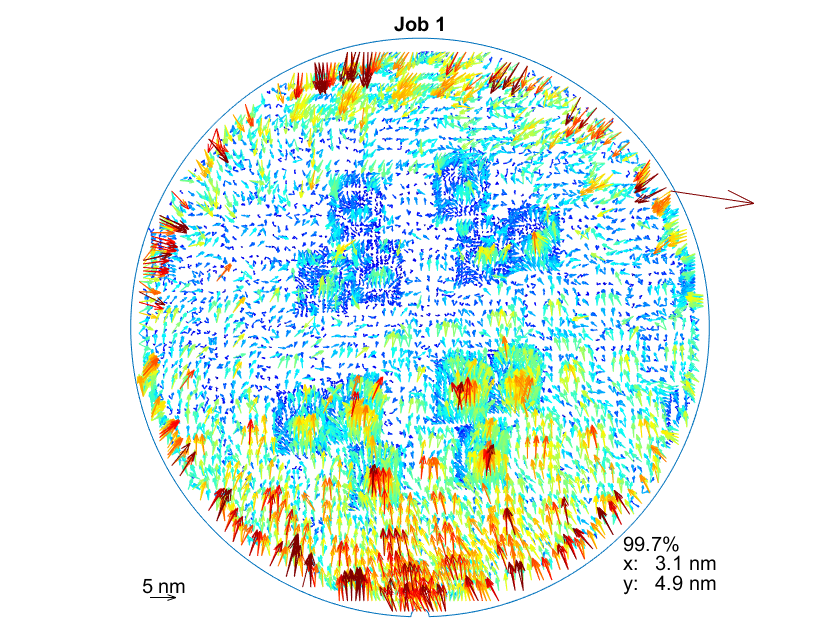

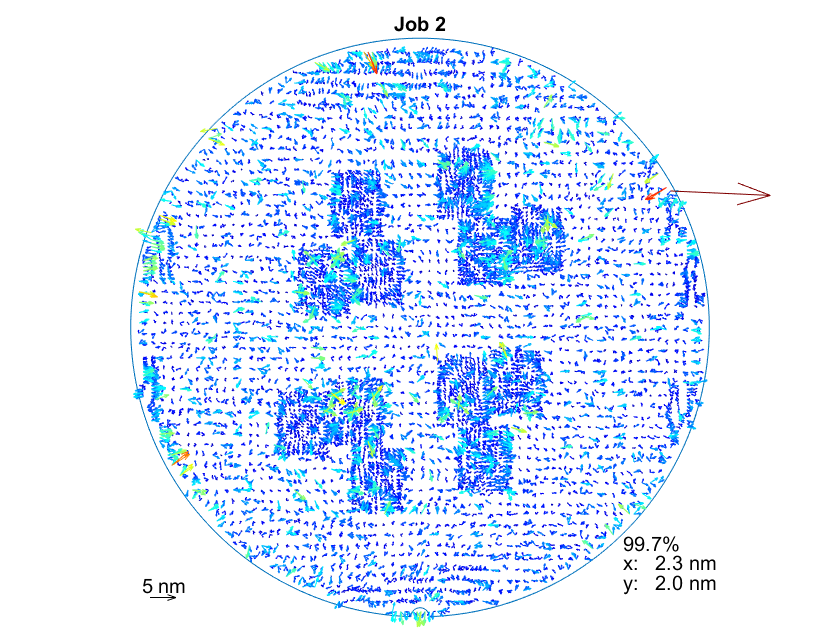

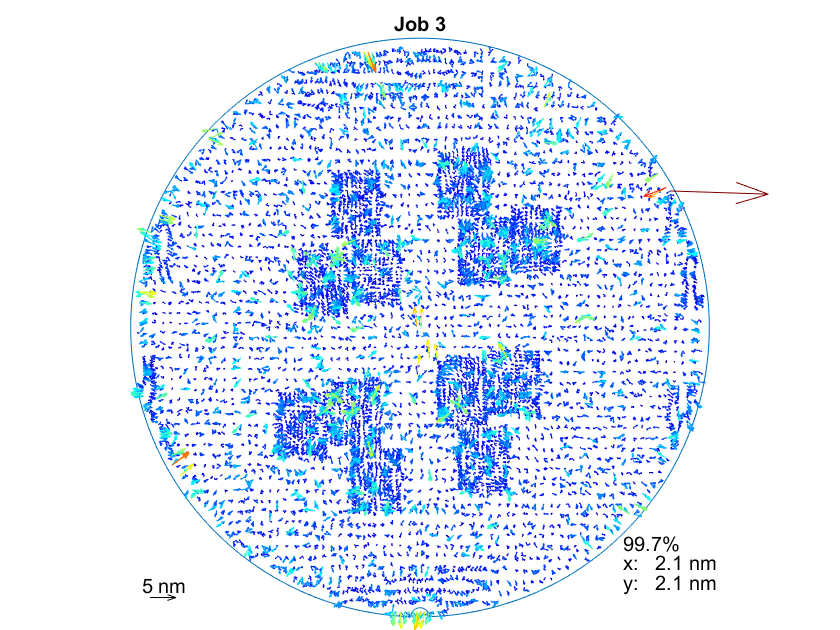

% Wafer plots of output (controlled overlay of the simulated jobs)
for jobIndex = 1:length(inputStructs)
    figure; wdmFig(jobIndex) = ovl_plot(rerunExampleBL3.rerunOutput(jobIndex).bmmoInputsRecorrected, 'vcolor', 'scale', 5e-9, 'title', ['Job ' num2str(jobIndex)]);
    ppt.insertFigures('Controlled Overlay of rerunExample', '', wdmFig(jobIndex))
end

## Comparing BMMO NXE against BL3 on a 3600D

Now we want to make a fair comparison between BL3 and BMMO NXE. We just calculated how BL3 would perform on this data on a 3600D.  

However, the results that are currently in the zips were calculated using BMMO NXE on a 3400C. We now want to simulate BMMO NXE on a 3600D as well.

Hence, we do a re-run of the data, but with only the TwinScan type modified.

rerunBmmoNxe = bmmo_RerunTsActuation(inputStructs)

rerunBmmoNxe =   bmmo_RerunTsActuation with properties:

                 bmmoInputs: [1×3 struct]
                  recorrect: [1×1 bmmo_RecorrectTsActuation]
                rerunOutput: [0×0 struct]
    recorrectionFpsPerChuck: []
                  jobConfig: [1×1 struct]
          tsActuationConfig: @bmmo_3400C_model_configuration
                 timeFilter: 'DEFAULT'
       recoveryOnFirstInput: 0


In the following lines, we modify the TwinScan type and copy the previously created jobConfig. We only have to change jobConfig.bl3_model to 0 to select BMMO NXE modelling.

rerunBmmoNxe.tsActuationConfig = @bmmo_3600D_model_configuration;
rerunBmmoNxe.jobConfig = BL3defaultConfig;
rerunBmmoNxe.jobConfig.bl3_model = 0;
rerunBmmoNxe.recoveryOnFirstInput = true;
rerunBmmoNxe.run;

Using Inline SDM configuration:bmmo_3400C_model_configuration
Using Inline SDM configuration:bmmo_3600D_model_configuration
Using Inline SDM configuration:bmmo_3400C_model_configuration
Using Inline SDM configuration:bmmo_3600D_model_configuration
Using Inline SDM configuration:bmmo_3400C_model_configuration
Using Inline SDM configuration:bmmo_3600D_model_configuration
Using Inline SDM configuration:bmmo_3600D_model_configuration


Then, we want to calculate some delta to show the improvement of BL3 against BMMO NXE. One example is to check the controlled overlay. 

As mentioned before, we need to convert the outputs from single-mark-field to ml format using bmmo_process_input first.

% Convert outputs of second job to ml format
jobIndex = 2;
[controlledOverlayBL3, ~] = bmmo_process_input(rerunExampleBL3.rerunOutput(jobIndex).bmmoInputsRecorrected);
[controlledOverlayBmmoNxe, ~] = bmmo_process_input(rerunBmmoNxe.rerunOutput(jobIndex).bmmoInputsRecorrected);


Since for both reruns, the first job is a recovery, we don't expect any delta there. This is because the controlled overlay for both reruns is equal to the uncontrolled overlay in this job.

However, we should see some delta in the second job:

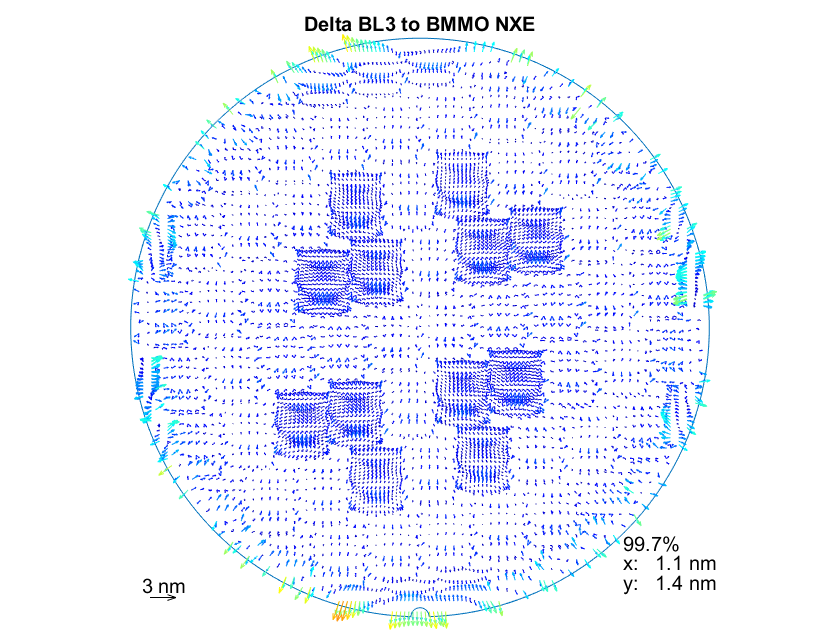

% Calculate delta of controlled overlay (BL3 vs BMMO NXE)
controlledOverlayDelta = ovl_sub(controlledOverlayBL3, controlledOverlayBmmoNxe);
fig = ovl_plot(controlledOverlayDelta, 'scale', 3e-9,'vcolor', 'title', 'Delta BL3 to BMMO NXE');
ppt.insertChapter('Rerun - delta BL3 to BMMO NXE on TS 3600D')
ppt.insertFigures('Delta BL3 to BMMO NXE, controlled ovl','', fig)

In order to close the PPT, run the next section. 

ppt.closeFile()

As we would expect, we mainly see intrafield and edge content in the delta. Intrafield content because BL3 on a 3600D can model and actuate splines, but BMMO NXE on a 3600D is restricted to 5th order content. The edge content is due to the introduction of the new edge model.

**NB**: This improvement is an overestimation of what would be seen by a customer. This is because on a 3600D, setup additionally calibrates using splines. Hence a part of this content would already have been caught and calibrated by setup. 